Load image

ba = imread('boccadasse.jpg');
ba = rgb2gray(ba);
r1 = imread('highway1.jpg');
r1 = rgb2gray(r1);
r2 = imread('highway2.jpg');
r2 = rgb2gray(r2);

Std dev = 1;

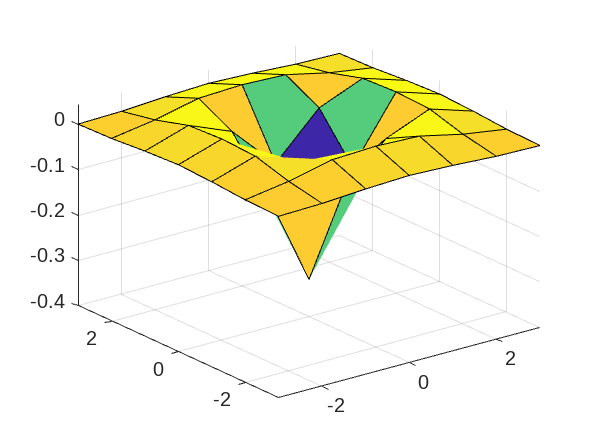

lap1 = Laplacian(1);

Std dev = 3.5;

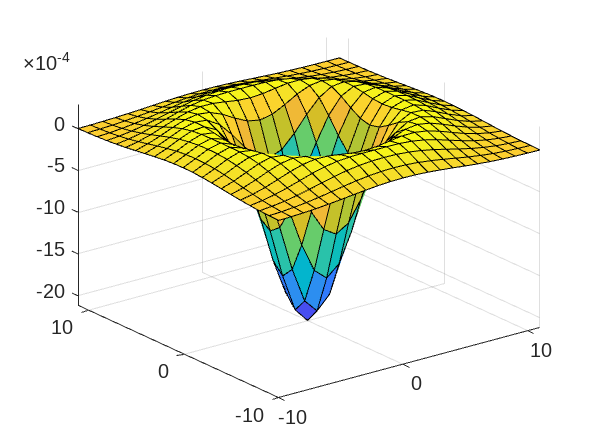

lap3 = Laplacian(3.5);

Convoluting

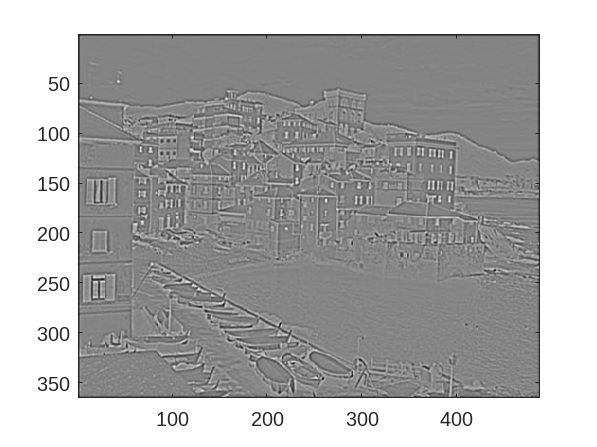

convLOG(lap1, ba);

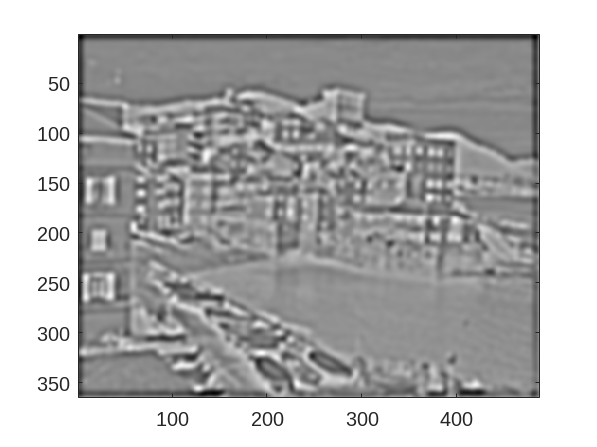

ret = convLOG(lap3, ba);

Edges

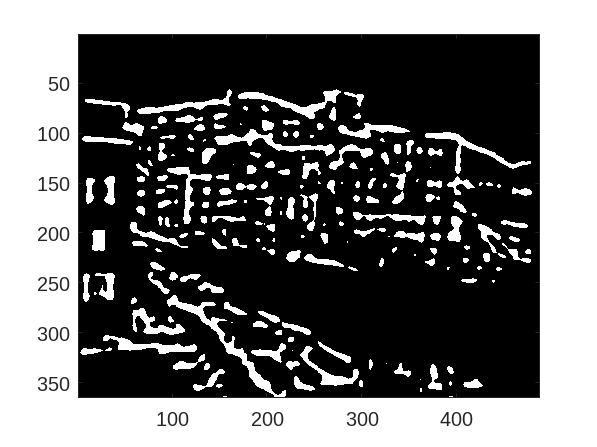

ed = edgesMine(ret);

zero crossings

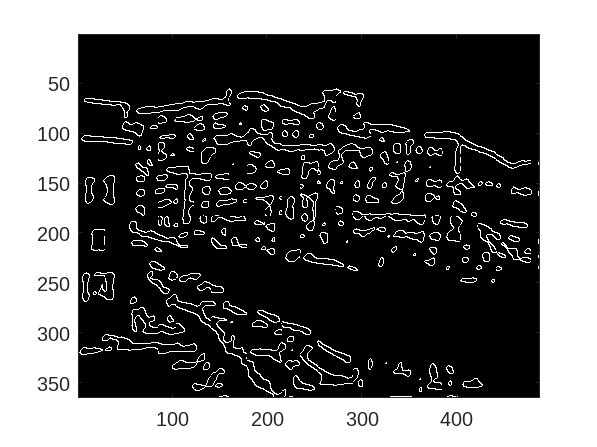

zero = ZeroCrossing(ed);

matlab

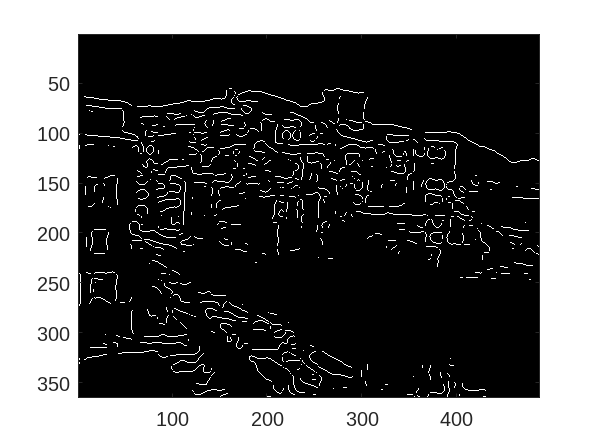

ans=edge(ba,'log', [],3.5);
figure, imagesc(edge(ba, 'log',[],3.5)), colormap gray

Straight lines

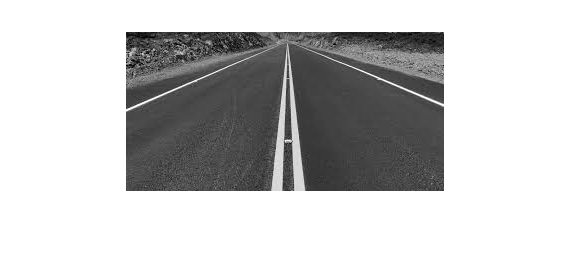

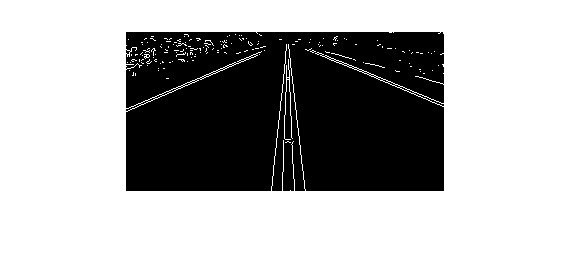

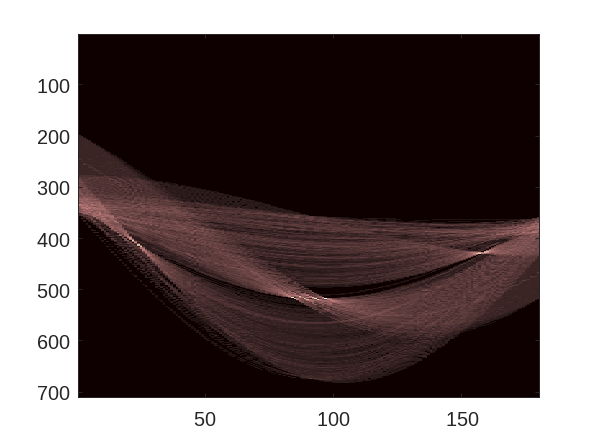

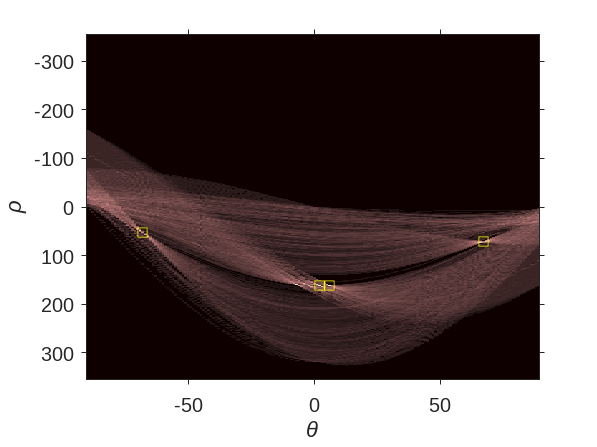

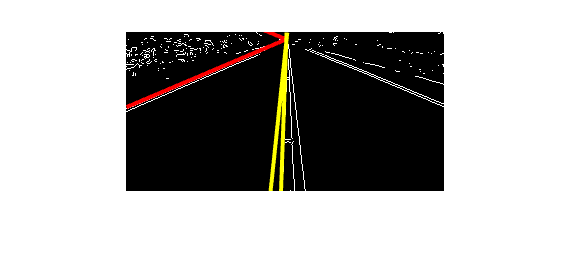

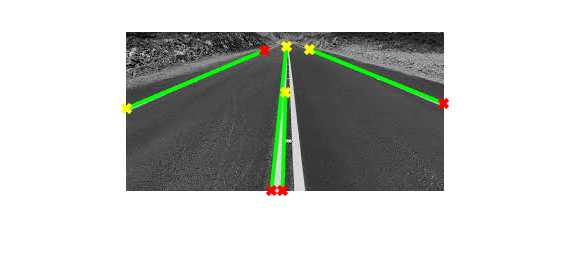

ex_hough(r1,4,true);

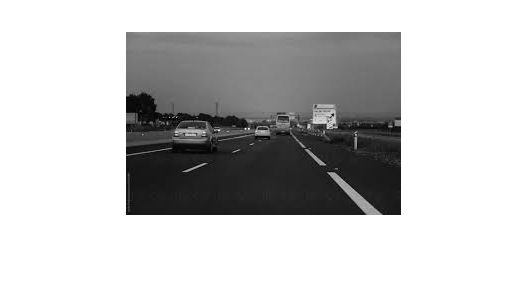

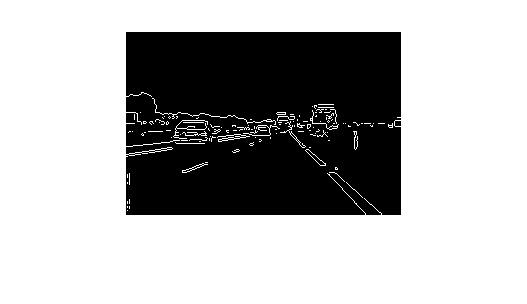

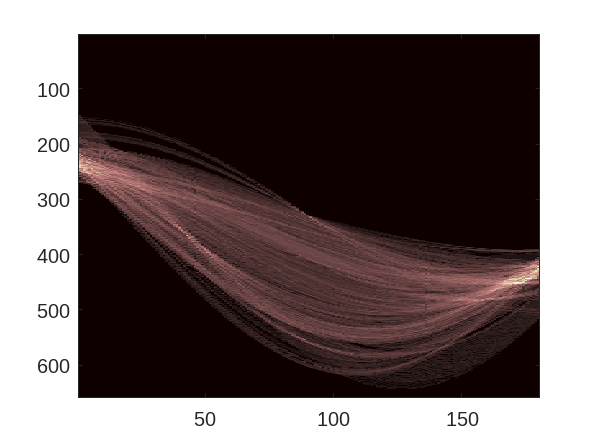

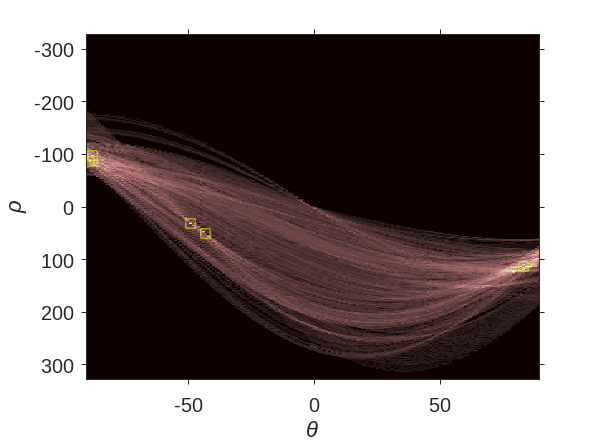

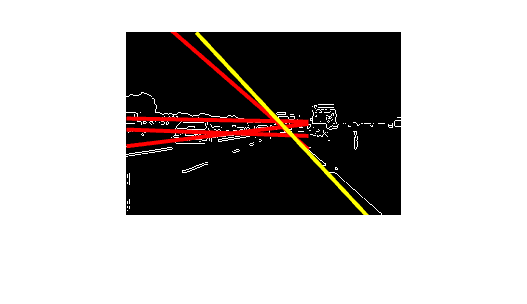

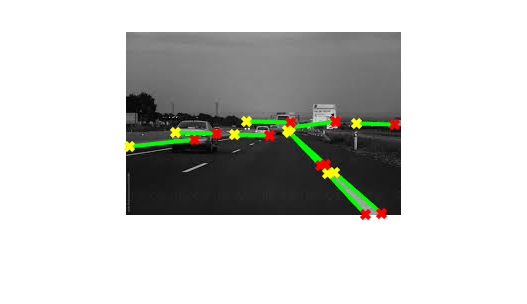

ex_hough(r2,5,false);